clc;clear;close all;
% 数学建模协会：Tongxin Ren，2019.10.9
% tongxin.r@gmail.com

# **MATLAB简介**

  MATLAB`是`Matrix&Laboratory`两个词的组合，意为矩阵工厂（矩阵实验室）。是由美国`Mathworks`公司发布的主要面对科学计算、可视化以及交互式程序设计的高科技计算环境。`

  MATLAB`和`Mathematica`、`Maple`并称为三大数学软件。它在数学类科技应用软件中在数值计算方面首屈一指。`MATLAB`可以进行矩阵运算、绘制函数和数据、实现算法、创建用户界面、连接其他编程语言的程序等，在工程计算、控制设计、信号处理与通讯、图像处理、信号检测、金融建模设计与分析等领域有广泛应用。`

# 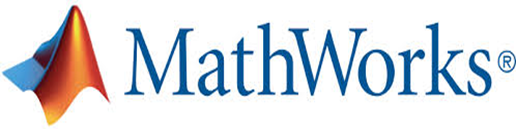

# **MATLAB功能**

1.`数值计算和符号计算功能`

    MATLAB`以矩阵作为数据操作的基本单位，还提供了十分丰富的数值计算函数。`

    MATLAB`和著名的符号计算语言`Maple`相结合，使得`MATLAB`具有符号计算功能。`

2.`绘图功能`

    MATLAB`提供了两个层次的绘图操作：一种是对图形句柄进行的低层绘图，另一种是建立在低层绘图操作之上的高层绘图操作。`

3.`编程语言`

    MATLAB`具有程序结构控制、函数调用、数据结构、输入输出、面向对象等程序语言特征，而且简单易学、编程效率高。`

4.**MATLAB**`工具箱`

    MATLAB`包含两部分内容：基本部分和各种可选的工具箱。`

    MATLAB`工具箱分为两大类：功能性工具箱和学科性工具箱``。`

***MATLAB是一个数值计算的工具软件，不是一门编程语言。大多数用MATLAB的人不是真正的程序员，而且不想成为（他们只关注数值计算）。***

# **MATLAB的安装**

MATLAB每年会更新两次，时间分别在3月和9月，对应的版本号是a和b，例如R2019a就代表是2019年3月发布的版本。

个人经验：最新版本往往是最好的，新版本往往会引入很多新的函数，在代码编写和运行效率上也会有所提升，所以推荐大家使用最新版本。

**如果发现MATLAB安装包特别大，电脑空间不足，可以考虑在安装过程中取消勾选不必要的工具箱，节省安装空间（慎重操作，部分工具箱之间存在依存关系）。**

[MATLAB是收费软件，上海交通大学软件授权中心提供正版下载，选择单机版，按照流程操作即可。](http://lic.si.sjtu.edu.cn/ )

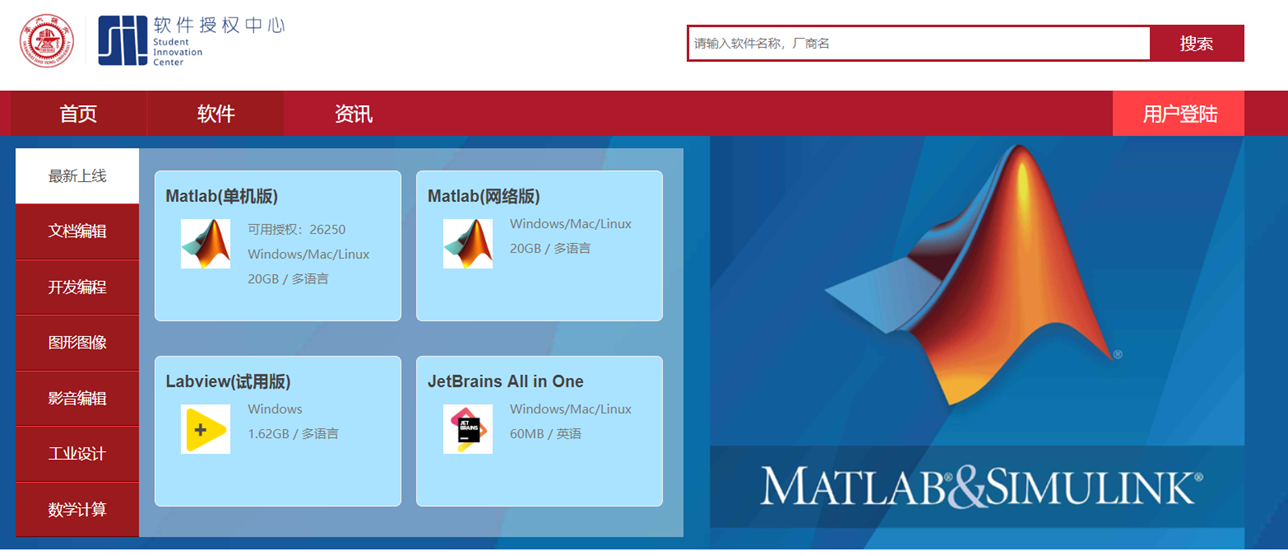

# **内容概述**

**通过本教程大家可以学会的：**

- MATLAB语法：一切操作的基础

- 使用MATLAB编写程序：函数和m文件的定义

- MATLAB绘图操作：图像的生成、格式修改和导出

- MATLAB进一步学习的方向：专业工具箱的使用、使用并行计算和矩阵计算提高效率

**本教程没有涉及的：**

- 这是一个MATLAB的编程教程，仅涉及语法，**不涉及算法**，大家可以自行尝试使用MATLAB实现简单的算法，可以从最简单的排序、动态规划、贪心、最短路算法等入手。也可以从科研或学习实际入手，实践是提高编程水平的最高效途径。

- 本教程不涉及各类专业工具箱的介绍和使用指南。 MATLAB是一个很全面的软件，涉及机械控制、图像处理、工程、物理学、化学、金融等多个领域，每个领域又有专业的工具箱，在掌握了基础的操作以后，各学科的同学可以根据需要深入了解专业工具箱的作用，这个内容已经远远超出了本次入门教程的范围。

- 本教程没有详细展开MATLAB中的面向对象编程。 面向对象编程是组织大型代码的常用方法，MATLAB在2008a以后也开始支持面向对象编程，面向对象编程是一种正式的编程方法，它将数据和相关操作（方法）合并到逻辑结构（对象）中。该方法可提升管理软件复杂性的能力——在开发和维护大型应用与数据结构时尤为重要。对于想要使用MATLAB进行数值分析和是可视化的同学来说，数据往往是简单的，此时面向对象编程的优势不太明显。但是，如果我们想要使用MATLAB开发大规模的计算程序，例如一整套实验数据的处理程序，面向对象可能是你需要继续深入学习的知识

# **MATLAB界面介绍**

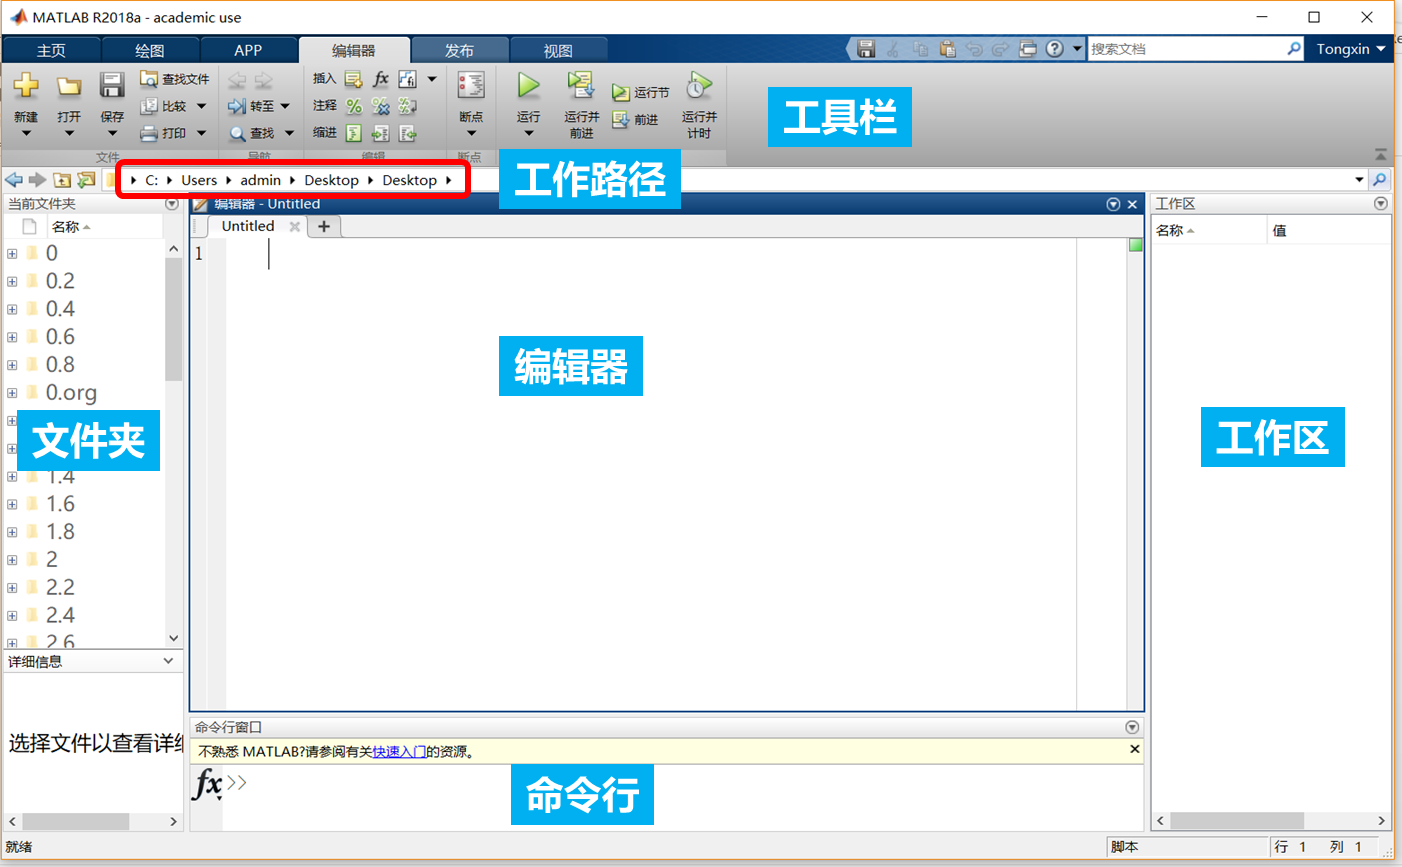

# **基本数据类型和操作**

**在matlab中提供了多种数据类型，包括浮点型和整形、字符和字符串、逻辑（True/False）表达式、函数句柄、结构数组、元胞数组、map容器、日期和时间、分类数组、表格和时间序列等等。这里我们对其中重要的几个展开解释。**

## **数值型**

**MATLAB中的数值包括有符号和无符号整数，单精度和双精度浮点数。默认情况下，matlab使用双精度浮点数存储数据。数值型数组或矩阵构造比较简单，这里简要概述如下：**

**数的四则运算和赋值语句**

a = 1

a = 1

b = 2  * 3

b = 6

c = a + b - 1

c = 6

d = a / b

d = 0.1667

sin(a^(1/2))

ans = 0.8415

`已经赋值的数据都可以在工作区``（`***workspace***`）``查看，如果不给定赋值对象，则系统会默认将计算结果赋值给“`**ans**”变量，后续的计算会覆盖之前的结果（类似计算器的功能）

`通过在命令行按“``↑``”“``↓``”箭头可以重复之前输入过的命令。`

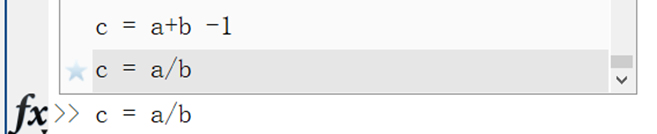

e = sin(a);

`通过添加分号可以省略命令行的输出`

**向量的生成**

**手动输入：**

`行向量：写在英文中括号`[]`内，数字间用“，”或者空格隔开`

a = [1 2 3 4]

a =      1     2     3     4


`列向量：写在英文中括号`[]`内，数字间用“；” 隔开`

b = [1 ; 2 ; 3 ; 4]

b =      1
     2
     3
     4


**有规律的数组可以利用“：”辅助输入，**`需要指定开始数字，结束数字和步长`

a = 1:2:10    %从1开始，到10结束，步长为2（步长可以省略，缺省值为1）

a =      1     3     5     7     9


**两个常用命令：**

**clc****： ** clears the Command Window，清空命令窗口

**clear****： **清空工作空间（储存的所有数据） 

**矩阵的生成**

**手动输入：**

`写在英文中括号`[]`内，数字间用“，”或者空格隔开，行与行之间用“；”隔开`


$$\left(\begin{array}{ccc}{1} & {2} & {3} \\ {4} & {5} & {6} \\ {7} & {8} & {10}\end{array}\right)$$


a = [1 2 3; 4 5 6; 7 8 10]

a =      1     2     3
     4     5     6
     7     8    10


**利用矩阵生成函数：**


$$\left(\begin{array}{ccc}{0} & {0} & {0} \\ {0} & {0} & {0}\end{array}\right)$$


z = zeros(2,3)%其中第一个参数为行数，第二个参数为列数

z =      0     0     0
     0     0     0


`类似的，还有`ones`，`rand`函数。`

**利用已定义向量合并:**

a = [1 2 3];
b = [4 5 6];
c = [a,b]

c =      1     2     3     4     5     6


**矩阵索引**

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


**访问矩阵中单个元素的方法:**

A(3,2) %指定行和列，第一个输入是行数，第二个输入是列数，从1计数（区别于其他编程语言的从0计数）

ans = 9

A(3,2) = 17                              %修改矩阵元素

A =      8     1     6
     3     5     7
     4    17     2


**矩阵切片:**

A(1:3,2)

ans =      1
     5
    17


A(:,2)     %等价于A(1:3,2) 

ans =      1
     5
    17


A(1:2,1:2)

ans =      8     1
     3     5


**矩阵计算**

**矩阵与数的四则运算:**

a = [1 2 3; 4 5 6; 7 8 10]

a =      1     2     3
     4     5     6
     7     8    10


a + 10

ans =     11    12    13
    14    15    16
    17    18    20


**函数作用在矩阵上**

sin(a) % 等价于函数作用在每一个元素上（请注意这个定义不同与数学中的矩阵函数）

ans =     0.8415    0.9093    0.1411
   -0.7568   -0.9589   -0.2794
    0.6570    0.9894   -0.5440


**矩阵的加法:**

b = a + a'             %对应元素相加，右上角加英文单引号得到矩阵的转置

b =      2     6    10
     6    10    14
    10    14    20


**多个矩阵的合并:**

[a; a]          %“，”横向（按照行）合并，“；”纵向（按照列）合并

ans =      1     2     3
     4     5     6
     7     8    10
     1     2     3
     4     5     6
     7     8    10


**矩阵求逆:**

a = [1 2 3; 4 5 6; 7 8 10]

a =      1     2     3
     4     5     6
     7     8    10


inv(a)

ans =    -0.6667   -1.3333    1.0000
   -0.6667    3.6667   -2.0000
    1.0000   -2.0000    1.0000


**矩阵点乘:**

p = a*inv(a)

p =     1.0000   -0.0000   -0.0000
    0.0000    1.0000   -0.0000
    0.0000   -0.0000    1.0000


**矩阵元素的乘法:**

p = a.*a 

p =      1     4     9
    16    25    36
    49    64   100


**矩阵乘方**

a^3

ans =          489         600         756
        1104        1353        1704
        1828        2240        2821


**矩阵元素的乘方**

a.^3

ans =            1           8          27
          64         125         216
         343         512        1000


**矩阵计算实例**


$$f(x)=x^{2}+x \sin (3 x)+1$$


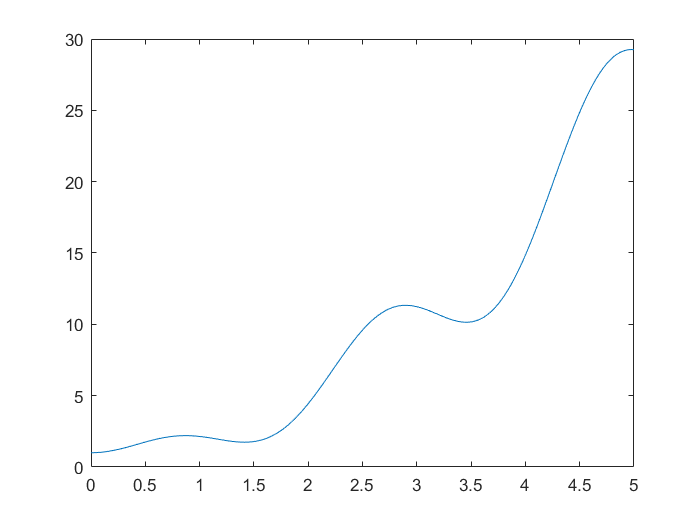

x = 0 :0.01:5; % 生成x向量
y = zeros(length(0 :0.01:5),1); % 初始化y向量
for i =1:length(x)
    y(i) =x(i)^2 + x(i) * sin(3*x(i))+1; % 在循环中按照公式更新y向量
end
plot(x,y)  % 画图

x = 0 :0.01:5 % 生成x向量

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y = x .^2 + x .* sin(3*x) + 1 % 根据矩阵乘法更新y向量

y =     1.0000    1.0004    1.0016    1.0036    1.0064    1.0100    1.0143    1.0195    1.0254    1.0321    1.0396    1.0477    1.0567    1.0663    1.0767    1.0877    1.0995    1.1119    1.1249    1.1386    1.1529    1.1678    1.1833    1.1993    1.2159    1.2329    1.2505    1.2685    1.2869    1.3058    1.3250    1.3446    1.3645    1.3848    1.4053    1.4261    1.4471    1.4683    1.4897    1.5112    1.5328    1.5545    1.5763    1.5981    1.6198    1.6416    1.6633    1.6848    1.7063    1.7276


plot(x,y) % 画图

## **逻辑型**

**所谓逻辑型数据，就是仅有"True"和“False”两个数值的一种数据类型。**

**创建逻辑矩阵或者数组的函数主要有三个：**

- **logical 函数：将非零元素装换为true，零元素转换为false**

- **true函数：产生全部元素为逻辑true的数组**

- **flase函数：产生全部元素为逻辑false的数组**

A = [-1,0,1;2,3,0;0,-1,2]

A =     -1     0     1
     2     3     0
     0    -1     2


L1 = logical(A)

L1 = 3×3 logical 数组
   1   0   1
   1   1   0
   0   1   1


**我们还可以使用函数创建逻辑数组**

A = [-1,0,1;2,3,0;0,-1,2]

A =     -1     0     1
     2     3     0
     0    -1     2


L1 = A>1

L1 = 3×3 logical 数组
   0   0   0
   1   1   0
   0   0   1


whos

  Name      Size             Bytes  Class      Attributes

  A         3x3                 72  double               
  L1        3x3                  9  logical              
  a         3x3                 72  double               
  ans       3x3                 72  double               
  b         3x3                 72  double               
  c         1x6                 48  double               
  d         1x1                  8  double               
  e         1x1                  8  double               
  i         1x1                  8  double               
  p         3x3                 72  double               
  x         1x501             4008  double               
  y         1x501             4008  double               
  z         2x3                 48  double               



**可以看到，逻辑类型的数组中每一个元素仅仅占用了一字节的内存空间。**

**逻辑数组能够帮助我们索引符合条件的元素，例如我们可以通过如下方法，得到矩阵中所有大于1的元素**

A(A>1)

ans =      2
     3
     2


## **Matlab中的字符**

MATLAB`中字符常用于程序输出，绘图操作等。字符用单引号。`(MATLAB 2017a`后也引入了双引号，有兴趣的同学可以自行了解`)，这里列举几个常用的字符串操作。

myText = 'hello world'

myText = 'hello world'

myText(1)

ans = 'h'

otherText = 'You''re right'

otherText = 'You're right'

longText = [myText,' - ',otherText] % 直接使用数组进行字符串的加和

longText = 'hello world - You're right'

f = 71;
c = (f-32)/1.8;
tempText = ['Temperature is ',num2str(c),'C']

tempText = 'Temperature is 21.6667C'

## **高维数组**

`产生一个三维的共`3*4*5=60`个元素的正态分布数组`

R = randn(3,4,5);

`三维数组可以代表一个三维空间内的温度场、速度场或者一个随时间变化的二维空间的数据等。`

p = perms(1:4);
A = magic(4);
M = zeros(4,4,24);
for k = 1:24
  M(:,:,k) = A(:,p(k,:));
end

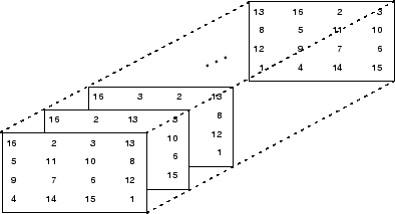

## Cell`数组`

Cell`数组允许不规则维度数据的存储，对数据的格式也没有限制，是一个兼容并包的数据类型。元胞数组的内存空间是动态分配的。`

M = cell(8,1);
for n = 1:8
  M{n} = magic(n);
end
M

M = 8×1 cell 数组
    {[       1]}
    {2×2 double}
    {3×3 double}
    {4×4 double}
    {5×5 double}
    {6×6 double}
    {7×7 double}
    {8×8 double}


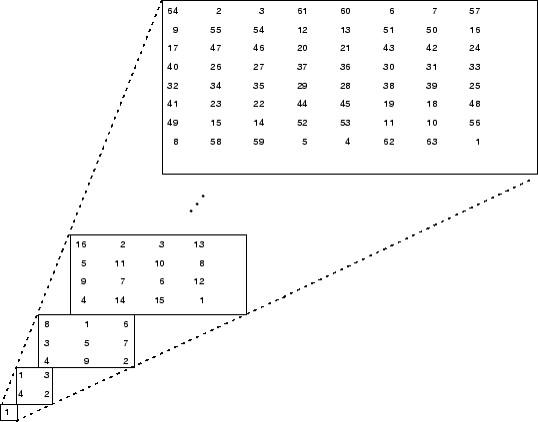

## **结构数组**

**与元胞数组一样，使用结构数组的目的也是存储多种类型的数据。结构数组与元胞数组有着非常相似的功能，但二者有所区别，区别主要在元素的索引上。结构数组通过域名访问数据，而元胞数组通过数字下标访问数据。这里给出了一个结构数组的创建和访问方法。**

S.name = 'Ed Plum';
S.score = 83;
S.grade = 'B+'

S = 包含以下字段的 struct :
     name: 'Ed Plum'
    score: 83
    grade: 'B+'


S(2).name = 'Toni Miller';
S(2).score = 91;
S(2).grade = 'A-';

S(3) = struct('name','JerryGarcia',...
'score',70,'grade','C')

S = 包含以下字段的 1×3 struct 数组:
    name
    score
    grade


scores = [S.score]

scores =     83    91    70


names = {S.name}

names = 1×3 cell 数组
    {'Ed Plum'}    {'Toni Miller'}    {'JerryGarcia'}


grades = {S. grade}

grades = 1×3 cell 数组
    {'B+'}    {'A-'}    {'C'}


## Map 容器

m = containers.Map() %生成和初始化方法


m = 

  Map - 属性:

        Count: 0
      KeyType: char
    ValueType: any



m('2r175') = 'Susan'

m =   Map - 属性:

        Count: 1
      KeyType: char
    ValueType: any


m('7g651') = 'Pete'

m =   Map - 属性:

        Count: 2
      KeyType: char
    ValueType: any


m('7g651') % 访问方法

ans = 'Pete'

## 其他数据格式

除了上面介绍的数值型、逻辑型、字符串、结构数组、元胞数组和map容器之外，MATLAB还提供了日期格式、表格式等。这里我们展开其中的表格式，日期格式大家有兴趣可以自行了解。

# **MATLAB绘图**

`最基本的绘图函数是`plot()`，根据输入参数，有着多种不同形式。`

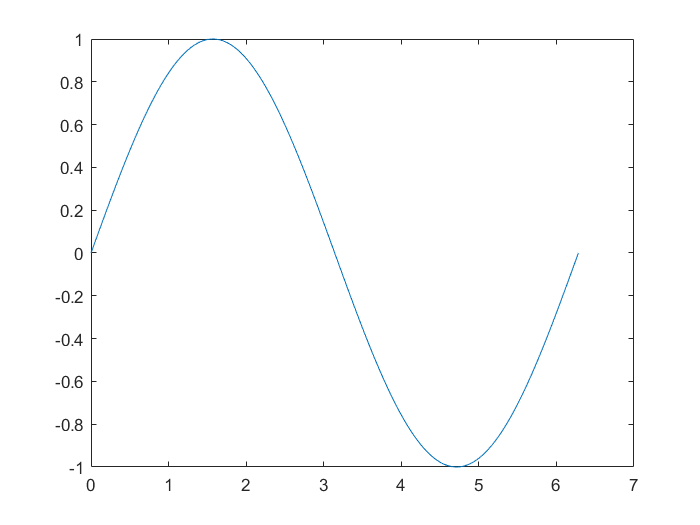

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y)  % 以向量x的元素为横坐标，向量y的元素为纵坐标画图

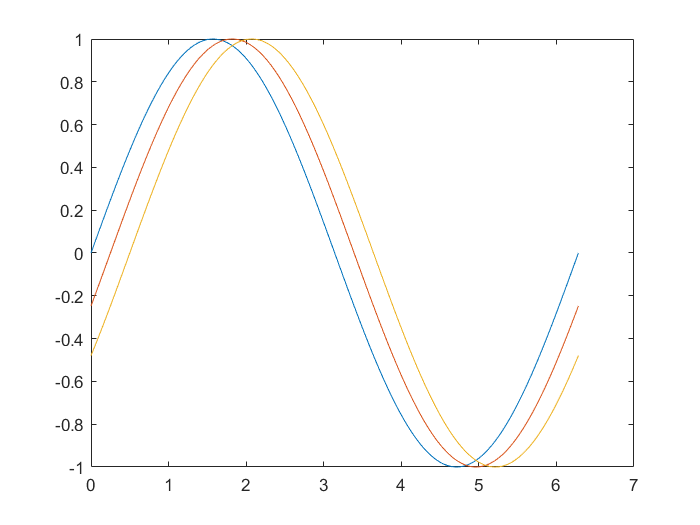

x = 0:pi/100:2*pi;
y = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
plot(x,y,x,y2,x,y3)  % 同时在图中绘制三组数据

x = linspace(0,2*pi,201);  % 将0到2π划分为201个值
y = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
x = [x;x;x]';
y = [y;y2;y3]';
plot(x,y)  % 将矩阵作为输入参数，则按列选择横/纵坐标

x1 = 0:pi/100:2*pi;
x2 = 0:pi/10:2*pi;
plot(x1,sin(x1), 'r:',x2,sin(x2), 'r+')

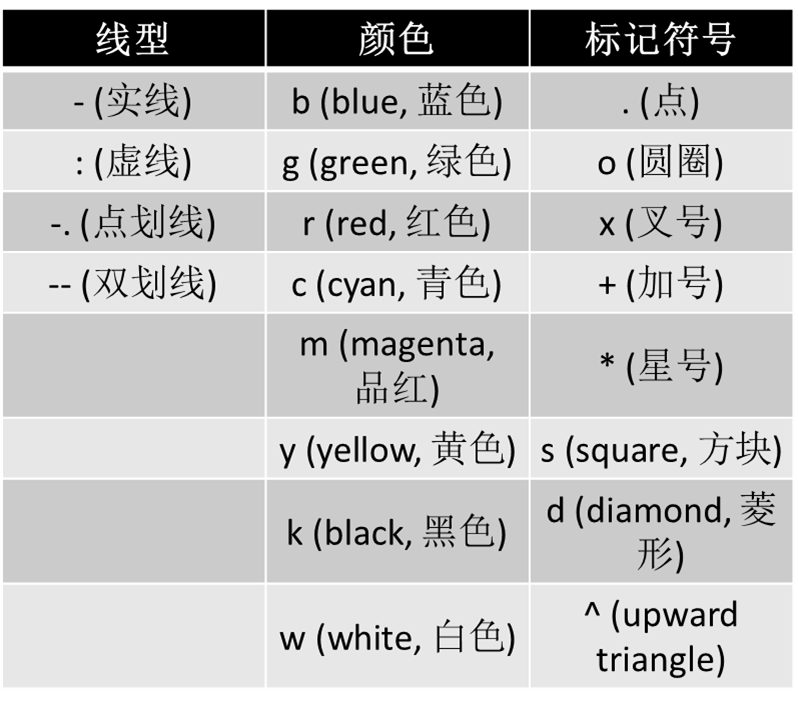

## **标注和坐标控制**

title('图形名称')  % 添加标题
xlabel('x坐标轴标题')  % 添加坐标轴标题
ylabel('y坐标轴标题')
text(4,0.2, '文字说明')  % 在指定位置添加文字说明
legend('图例1', '图例2')  % 添加图例，指定图例名称

`标注文字除了`ASCII`字符外，还可以使用`LaTeX`格式的控制字符来添加特殊字符、符号甚至公式等内容。在此仅举一个简单例子。`

xlabel('-{\pi} {\leq} {\itt} {\leq} {\pi}')  % 将x轴标题设置为-π≤t≤π

`绘制图形时，`MATLAB`会自动根据数据范围选择坐标范围，但也可以手动调整。`

axis off % 关闭坐标轴，反之用axis on
grid on  % 添加网格线，反之用grid off
box on  % 添加坐标边框，反之用box off

## **文字字体、大小、坐标刻度等细节调整**

`此类细节调整一般通过`gca`实现，`gca`可返回当前坐标图的句柄。`

get(gca)  %查看当前坐标图的所有参数信息

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'outerposition'
                 AlphaScale: 'linear'
                   Alphamap: [1×64 double]
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'on'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [3.5000 0 17.3205]
         CameraPositionMode: 'auto'
               CameraTarget: [3.5000 0 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [3×1 Graphics]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
            ColorOrd

gca`的参数信息中，包含了字体、大小、刻度等常见的项目，可对照进行修改。`

set(gca, 'FontSize', 15)

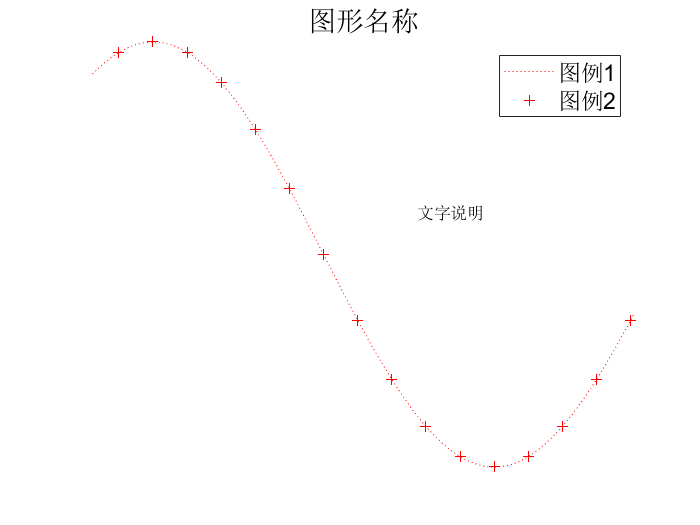

set(gca, 'XLim', [1,6], 'XTick', [1:0.5:6], 'TickDir', 'out', 'XMinorTick', 'on')

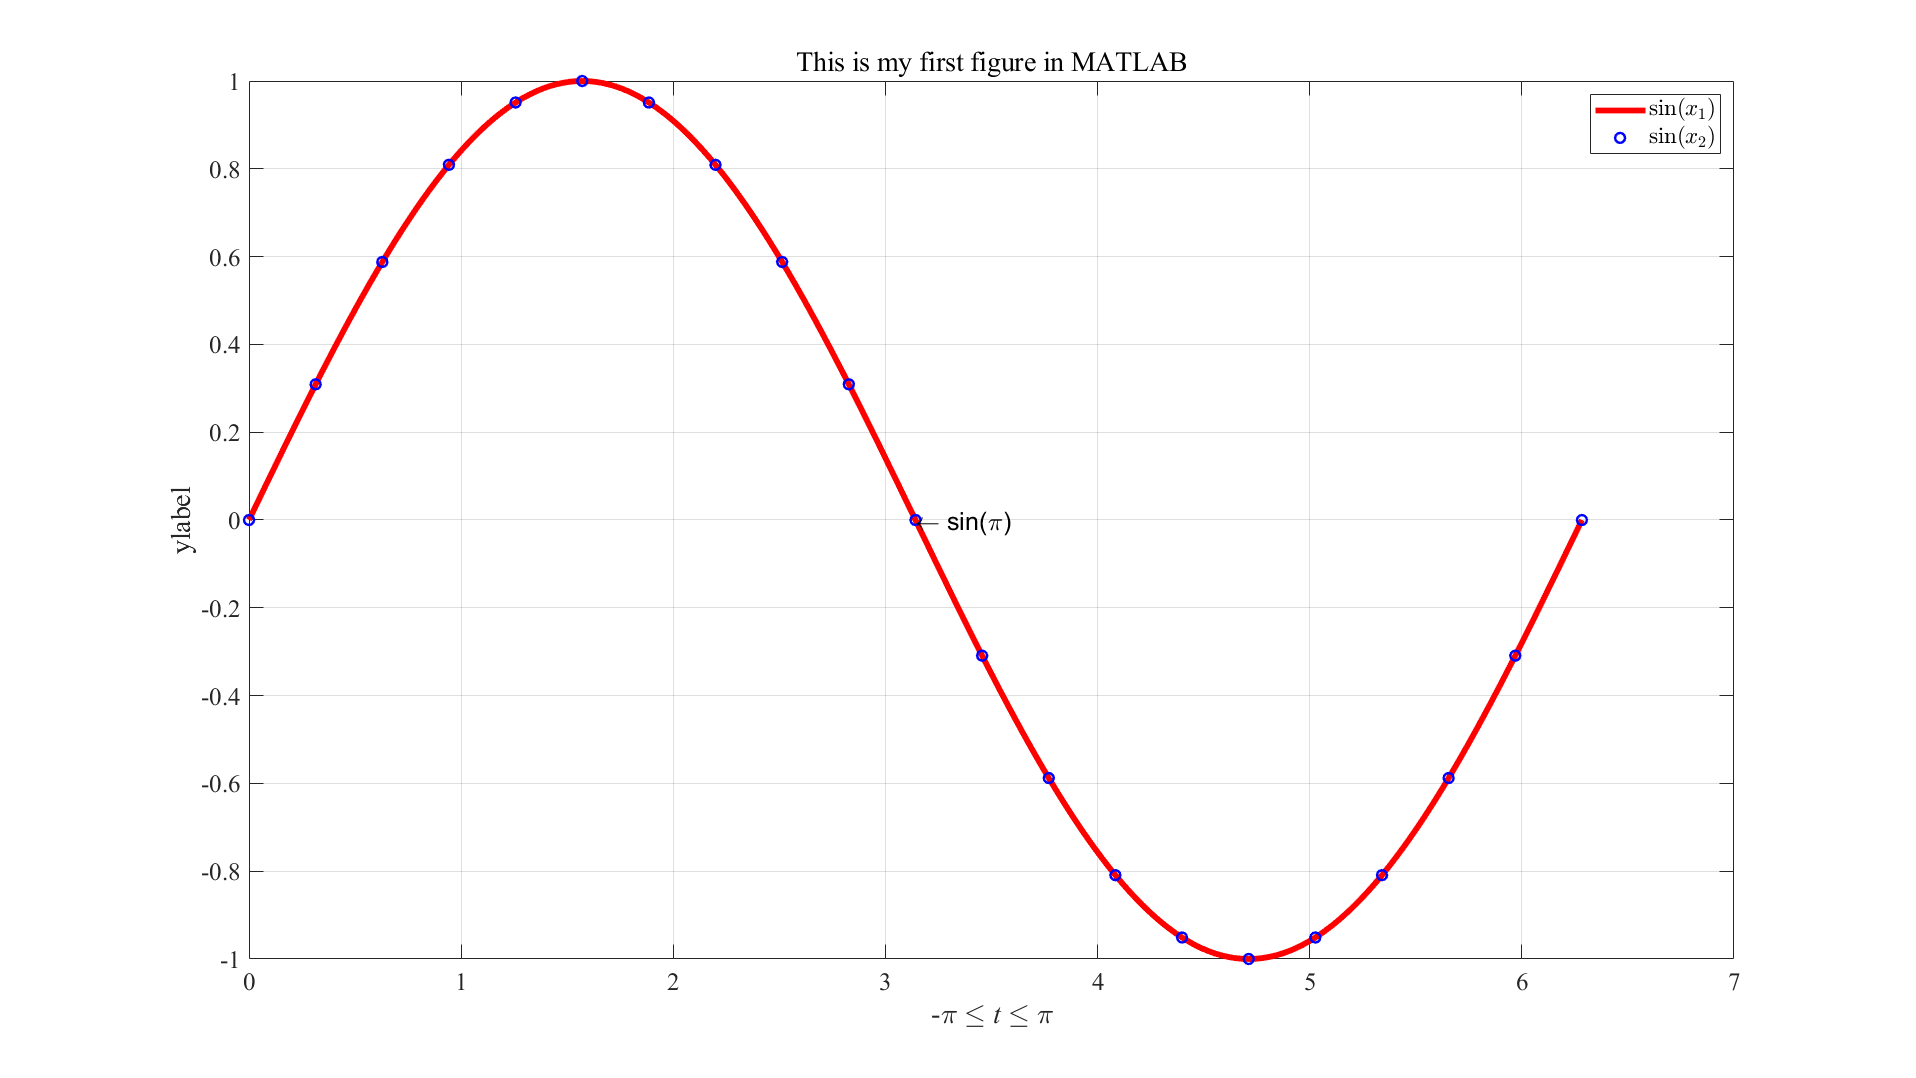

x1 = 0:pi/100:2*pi; x2 = 0:pi/10:2*pi;
plot(x1,sin(x1), 'r', 'LineWidth',3.5); hold on;
plot(x2,sin(x2), 'bo', 'LineWidth',1.5);
title('This is my first figure in MATLAB')  % 添加标题
xlabel('-{\pi} {\leq} {\itt} {\leq} {\pi}')  % 将x轴标题设置为-π≤t≤π
ylabel('ylabel'); grid on;
set(gcf,'outerposition',get(0,'screensize'));
text(pi,0,'\leftarrow sin(\pi)','FontSize',15)  % 在指定位置添加文字说明
h=legend('$$\sin(x_1)$$', '$$\sin(x_2)$$');
set(h,'Interpreter','latex')
set(gca, 'FontSize', 15, 'FontName', 'Times New Roman')

%set(gca, 'XLim', [1,6], 'XTick', [1:0.5:6], 'TickDir', 'out', 'XMinorTick', 'on')

## **图形保持和窗口分割**

`若希望在已有的图形上继续添加新的图形，可以使用图形保持命令`hold`。`

`在一个图形窗口`(figure)`中绘制多个独立图形，可将图形窗口分割成若干个`subplot`，每个子图形都可以单独进行调整。`

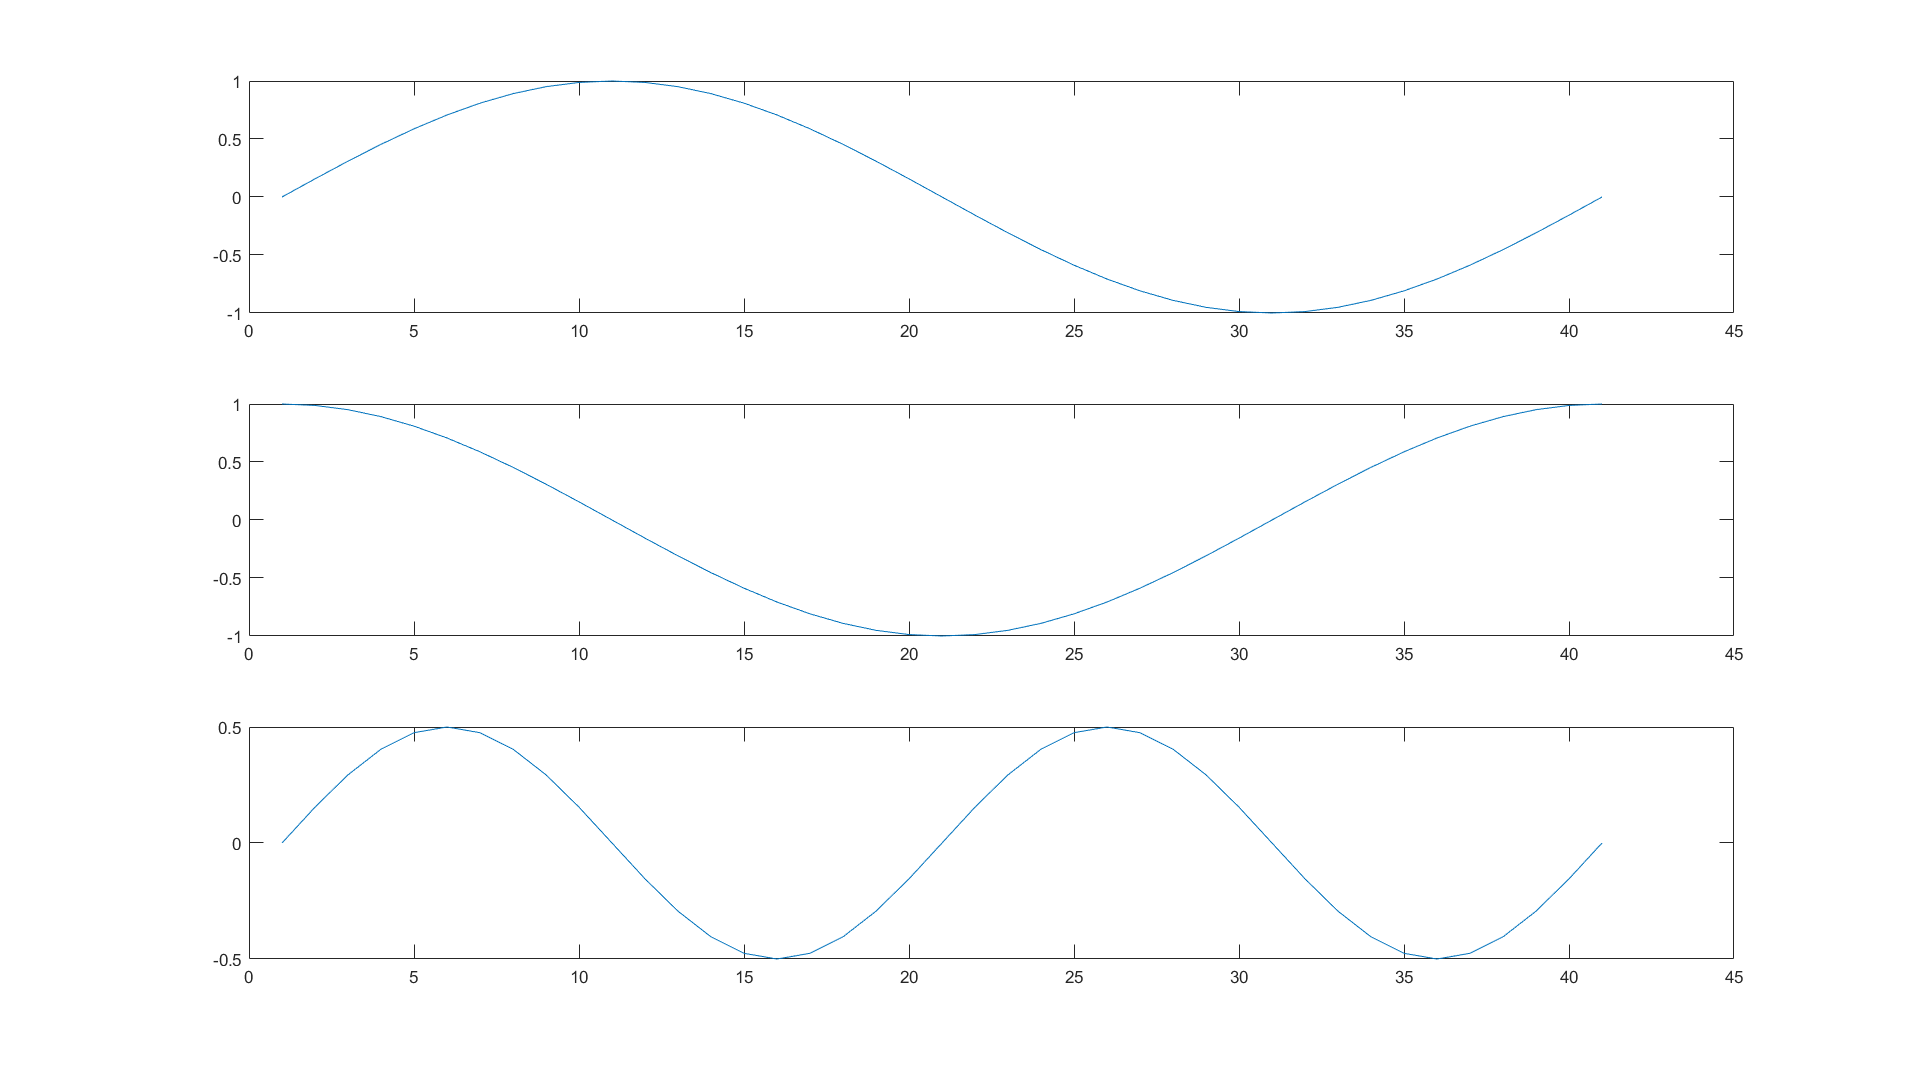

x = 0:pi/20:2*pi;
subplot(3,1,1); plot(sin(x))  % 控制3X1的子图形划分方式中的第一个子图形
subplot(3,1,2); plot(cos(x))  % 控制第二个子图形
subplot(3,1,3); plot(sin(x).*cos(x))  % 控制第三个子图形

**手动操作后的代码生成**

x1 = 0:pi/100:2*pi; x2 = 0:pi/10:2*pi;
%createfigure(x1,sin(x1),x2,sin(x2))

## **其他二维绘图函数**

**条形图/柱形图:**

x1=11:20

x1 =     11    12    13    14    15    16    17    18    19    20


y1 = 0.1:0.1:1

y1 =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


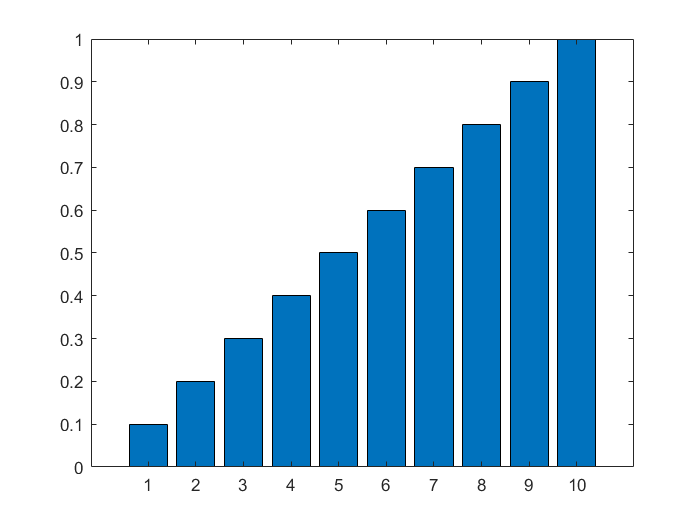

figure
bar(y1)  % 按向量y中元素数值绘制条形图，横坐标默认

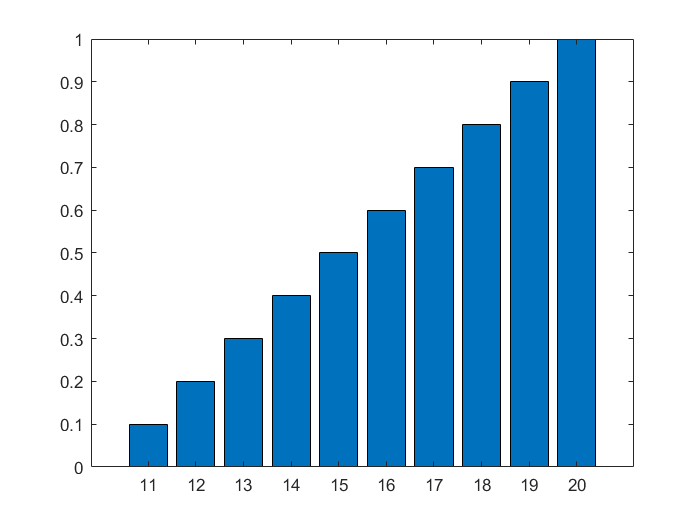

bar(x1, y1)  % 条形图横坐标由向量x给定

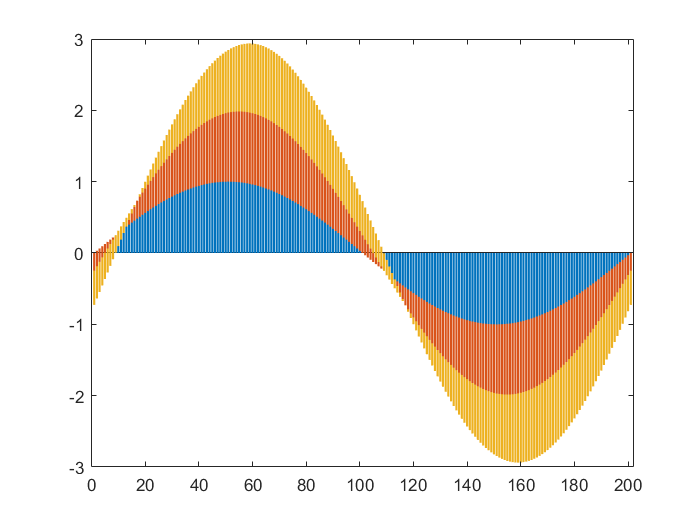

bar(y, 'stack')  %

绘制堆积条形图

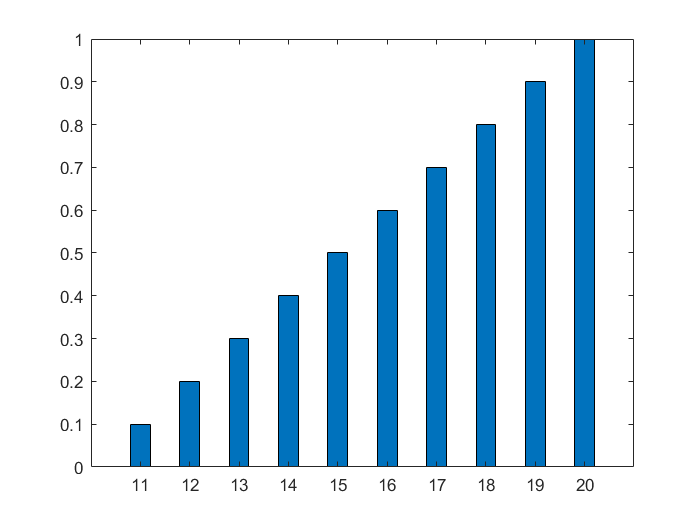

bar(x1, y1, 0.4)  % 将条形宽度更改为默认值的0.4倍

**杆图/火柴图**

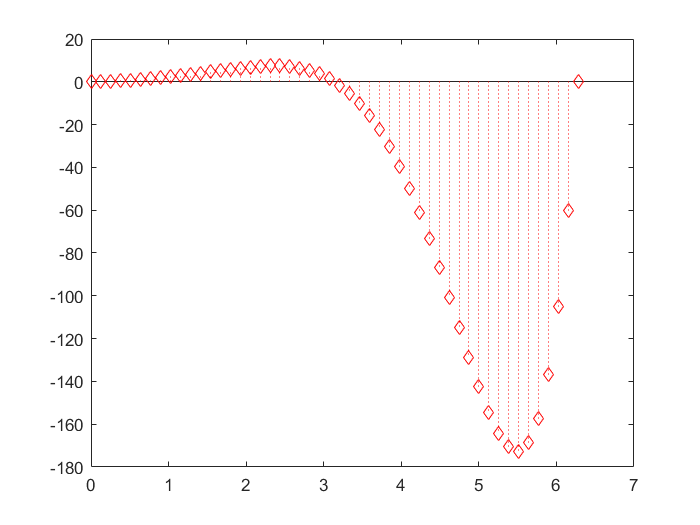

X = linspace(0, 2*pi, 50)';  % 用法与plot类似
Y = (exp(X).*sin(X));
stem(X, Y , ':dr')

**极坐标图**

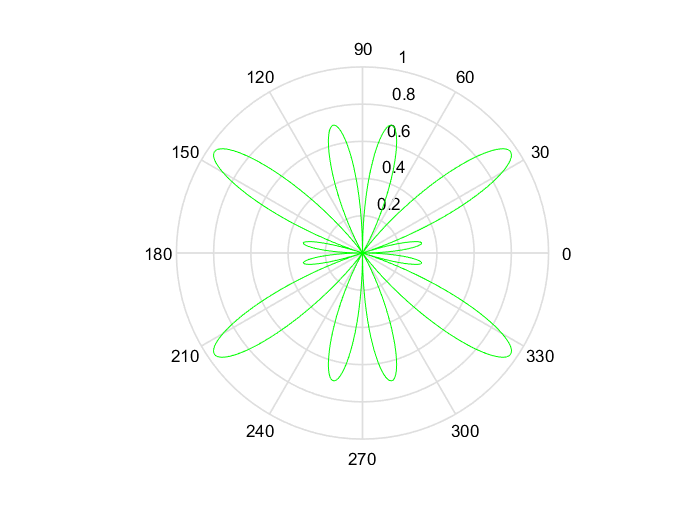

theta = 0:0.01:2*pi;
rho = sin(3*theta).*cos(5*theta);
polar(theta, rho, 'g')

**散点图**

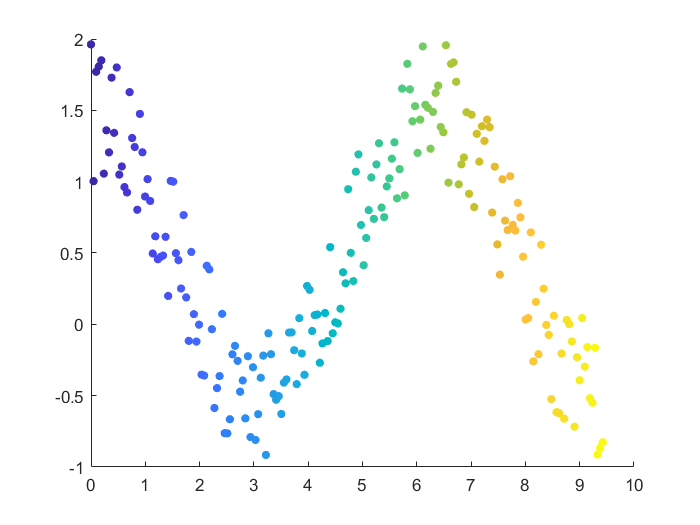

x = linspace(0, 3*pi, 200);
y = cos(x) + rand(1, 200);
a = 25; c = linspace(1, 10, length(x));  % a控制数据点的面积，c控制数据点的颜色
scatter(x, y, a, c, 'filled')  % filled表示实心数据点

**饼图**

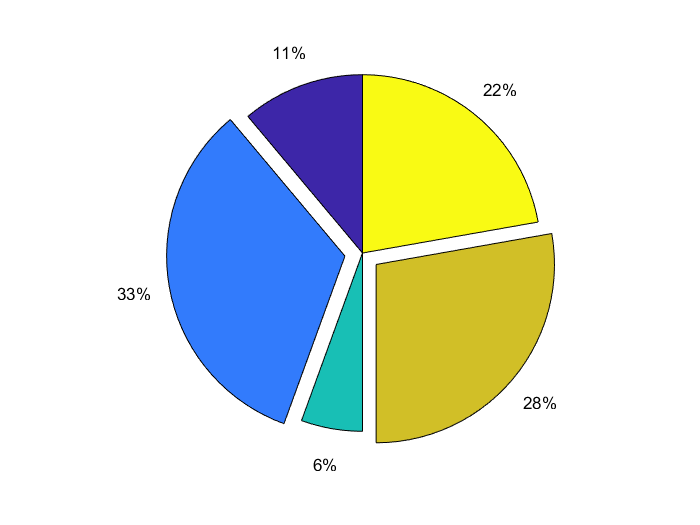

X = [1, 3, 0.5, 2.5, 2]; explode = [0, 1, 0, 1, 0];
pie(X, explode)  % 根据X中元素绘制饼图，其中第二、四块分离出来

## **三维绘图**

`首先需要生成平面区域内的网格坐标矩阵，常常通过`meshgrid()`函数完成。`

`随后可通过`mesh()`函数和`surf()`函数绘制三维曲面图。`

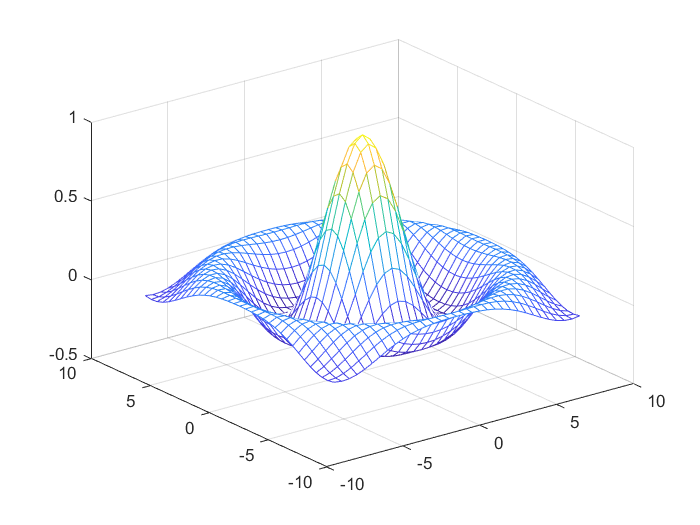

[X, Y] = meshgrid(-8:0.5:8);
R = sqrt(X.^2 + Y.^2)+eps;   % eps为MATLAB内置的小量，避免奇异点产生
Z = sin(R)./R;    % sinc函数
mesh(X, Y, Z)  % mesh()绘制网格图

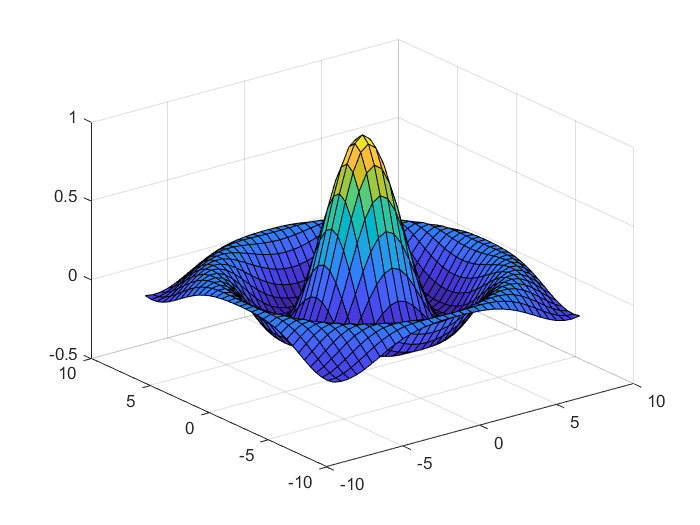

[X, Y] = meshgrid(-8:0.5:8);
R = sqrt(X.^2 + Y.^2)+eps;   
Z = sin(R)./R;    
surf(X, Y, Z)  % surf()绘制曲面图

`标注、坐标范围等细节调整与二维情况方法相同。`

## **三维绘图—进一步处理**

`对通过`surf()`生成的空间曲面图，还可以进行进一步的处理，优化视觉效果。`

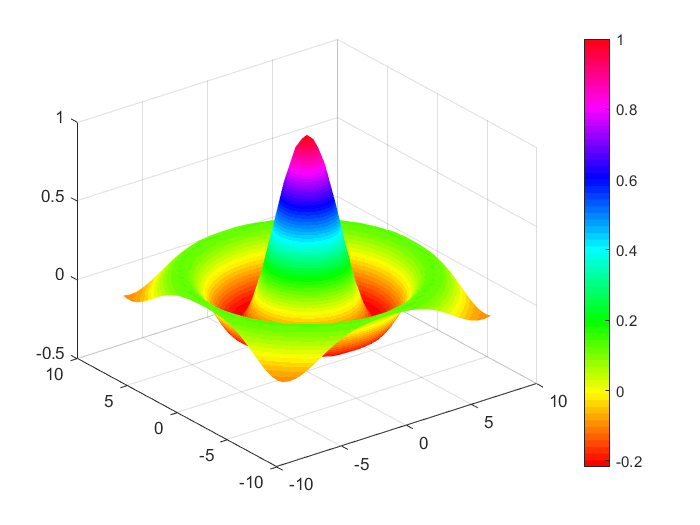

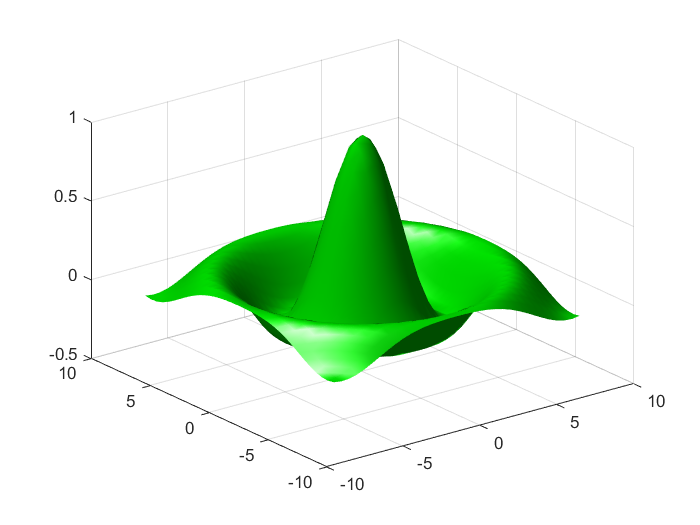

[X, Y] = meshgrid(-8:0.5:8);
R = sqrt(X.^2 + Y.^2)+eps;   
Z = sin(R)./R;  
surf(X, Y, Z)
colormap hsv  % 更换色系，可供选择的有default, hsv, spring, autumn等
colorbar  % 生成当前色系对应的参考色谱
shading interp  % 消去网格线

surf(X, Y, Z, 'FaceColor', 'g', 'EdgeColor', 'none')
camlight('left')  % 设置光源
lighting('gouraud')  % 采用Gouraud模型平滑着色

medium


`三维绘图的细节知识还有很多，同学们可以根据实际需要查阅参考资料或帮助信息。`

# **MATLAB流程控制**

**MATLAB**`流程控制`

         `（`1`）条件控制：`if, else, elseif

         `（`2`）循环控制：`for, while, continue, break

`程序文件`**——MATLAB**`编程的主要载体`

         `（`1`）`script`：脚本文件`

         `（`2`）`function`：函数文件`

## **条件控制语句 — If-else**

`条件控制语句能够在运行过程中根据条件即时选取需要执行的代码块。`

`最简单的控制语句为`if-else`语句。`

if-else`结构仅能进行二分；通过`elseif`可对代码块`2`再次进行条件控制，从而实现复杂划分。`

a = randi(100, 1);  % 生成一个随机整数

dayNum = 7

dayString = 'Saturday'

if a < 30  % 判断奇偶性
disp('small')  % 若a < 30，执行代码块1
elseif a < 80
disp('medium')  % 若30 <= a < 80，执行代码块2
else
disp('large')  % 上述条件均不满足(则a >= 80)，执行代码块3
end

Weekend!


## **条件控制语句 — Switch**

SWITCH`语句提供了一种直接根据多个可能条件进行划分的方式。`

[dayNum, dayString] = weekday(date, 'long', 'en_US')
switch dayString
     case 'Monday'
          disp('Start of the work week')
     case 'Tuesday'
          disp('Day 2')
     case 'Wednesday'
          disp('Day 3')
     case 'Thursday'
          disp('Day 4')
     case 'Friday'
          disp('Last day of the week')
     otherwise  % otherwise包含了所有之前的case中没有提及的可能
          disp('Weekend!')
end

**注意：MATLAB在执行switch语句时，只会执行第一个控制条件为真的代码块，随后退出整个条件控制结构，不考虑后续是否还有满足条件的情况。**

## **循环控制语句—for, while**

for`语句常用于执行循环次数固定的、或循环次数已经预先在程序中确定的循环结构。`

while语句常用于执行循环次数无法预先确定的循环结构，只要循环控制条件判断语句为真，循环就会不断地重复进行下去。

a = 0; fa = -Inf;  % 用二分法求解x^3-2*x-5=0近似值的程序段
b = 3; fb = Inf;
while (b - a) > 0.001       % eps是一个MATLAB预设的小量，用于表达精度
     x = (a+b)/2;
     fx = x^3-2*x-5;
     if sign(fx) == sign(fa)
          a = x; fa = fx;
     else
          b = x; fb = fx;

k = 50

     end  % 结束if-else结构
end  % 结束while循环

## **循环控制语句—Continue, break**

`可以采用`continue`和`break`对循环进行更精细的控制。`

continue: `忽略本次循环中`continue`后、`end`前的代码块，结束本次循环，回到循环结构的起点，开始下一次循环。`

break: `忽略本次循环中`break`后、`end`前的代码块，结束本次循环，跳出当前的循环结构。`

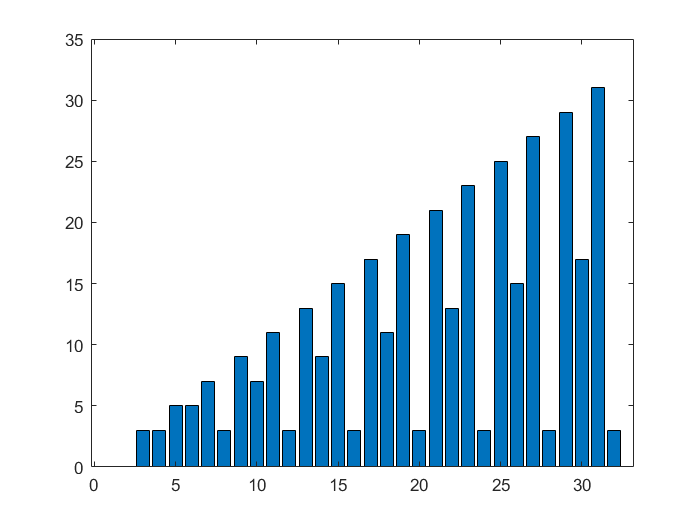

k = 0;
for i = 1:10
     if i == 5
     continue;  % 若将此处的continue换为break，结果将会是如何？
     else

          k = k+i;
     end  % 结束if-else结构
end  % 结束for循环结构
k

**注意：在存在多层嵌套循环的情况下，break只会跳出该语句所在的那一层循环，回到上一层循环。**

## **程序文件的编写—script**

`大多数情况下，在`MATLAB`命令窗口输入语句，均遵循“输入`—`执行”模式，类似于命令行和`Python`。处理复杂问题时，这种基本的操作方式可能造成不便。此时应考虑使用`script`或`function`进行编程。`

`新建一个`script`文件，键入下列代码：`

r = zeros(1,32);  % 统计3-32阶magic square的秩，并绘制柱状图
for n = 3:32

x = 0.0100

    r(n) = rank(magic(n));
end
bar(r)

`将脚本文件保存为“`magicrank.m”`。在命令窗口中直接键入：`

`执行完毕后`workplace`会有什么变化？`

## **程序文件的编写—Function**

`与`script`不同，`function`文件可以在调用的同时赋予输入参数，并且提供返回值。在调用函数的过程中产生的变量保存在函数自己的`workplace`中，而不是用户接触的`workplace`。`

MATLAB`中许多内置的函数都是通过这样的形式定义的，如`rank()`。`

`在`MATLAB`编程过程中，可能涉及多种不同类型的函数：匿名函数、`main`函数和`local`函数、`private`函数等。在此仅对相对常用的匿名函数进行介绍。`

## **提高程序运行效率**

`为提高`MATLAB`程序运行效率，可以考虑`

`向量化表达`

tic

时间已过 0.390764 秒。


x = 0.01
for k = 1:100001
     y(k) = log10(x);
     x = x + 0.01;

时间已过 0.010468 秒。


end
toc

tic
x = 0.01:0.01:1000;
y = log10(x); toc

`预分配变量空间`

`通常通过`zeros()`等函数为变量预先分配空间，能够显著提高循环执行速度。`

r = zeros(32,1);		% 为变量r预先分配空间，避免每次循环改变r的维度
for n = 1:32
     r(n) = rank(magic(n));

  Name            Size                 Bytes  Class                                  Attributes

  A               4x4                    128  double                                           
  B               3x5x2                  240  double                                           
  L1              3x3                      9  logical                                          
  M               8x1                   2528  cell                                             
  R              33x33                  8712  double                                           
  S               1x3                   1292  struct                                           
  X              33x33                  8712  double                                           
  Y              33x33                  8712  double                                           
  Z              33x33                  8712  double                                           
  a               1x1                  

end


**在语句后面加分号**

加分号可以减少不必要的输出

**考虑使用并行计算**

结合并行计算工具箱，用户可以把for循环替代为parfor，提高计算速度。

**导入数据使用load**

**选用合适的数据类型**

# **数据导入**

## **工作空间变量的保存和读取**

`当前`workspace`中的变量信息可以通过`whos`指令可以查看，也可以直接在主界面浏览工作区的信息`

A = magic(4);
B = rand(3,5,2);
whos

`在退出`MATLAB`程序时，`workspace`中的变量不会保留。`

`上述操作也可直接在主界面中完成。`

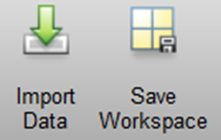

## **从excel文件中导入数据**

**通过xlsread()函数导入**

`若目标`excel`文件不在当前目录及`MATLAB`查找路径上时，需要在文件名前添加完整路径。`

**通过主界面Import Data导入**

`单击`Import Data`按钮，选取目标`excel`文件，在`MATLAB`的`Import`对话框中手动选取导入数据范围、设定导入的变量形式、无法导入的数据的替换或删除、导入后的变量名等等。`

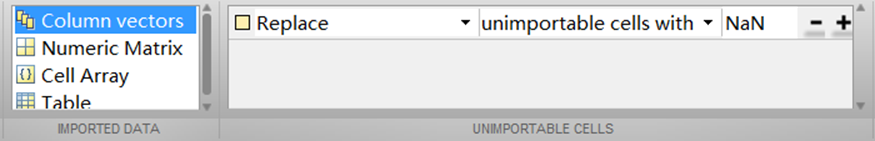

# **获取帮助**

`所有的`MATLAB`函数都有帮助文件，包括输入输出格式的介绍，调用语法等。有以下几种从命令行访问这些帮助文件的方法：`

**非官方但是非常有用的途径：**

**网络搜索想要实现的功能，看是否有已经有内置的函数**

**MATLAB使用案例:**[https://](https://www.mathworks.com/help/matlab/index.html)[www.mathworks.com/help/matlab/index.html](https://www.mathworks.com/help/matlab/index.html) 

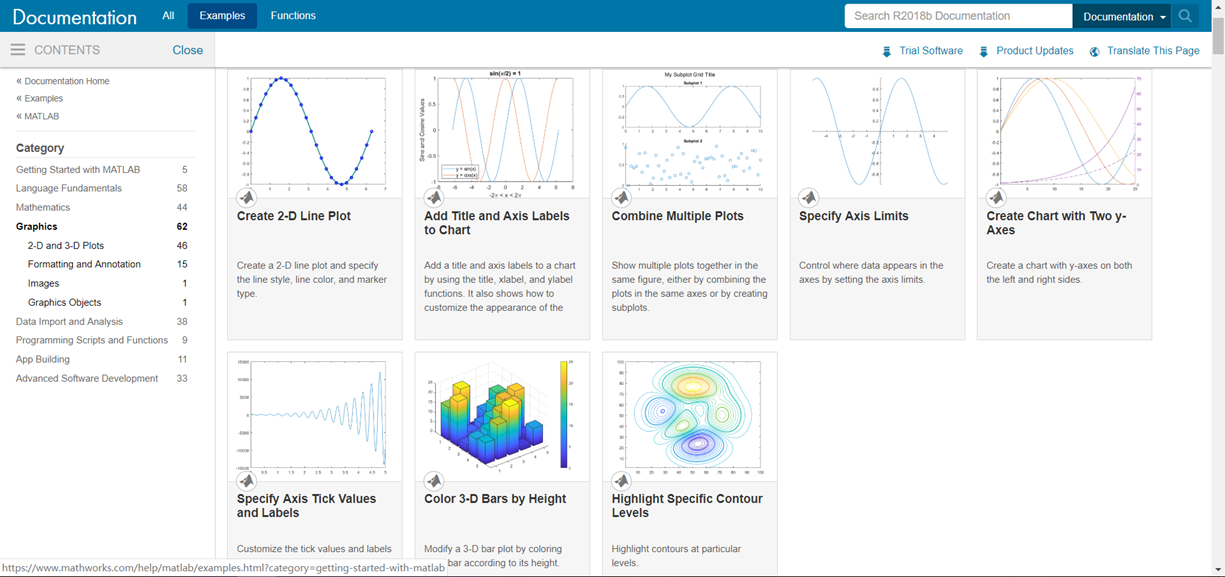

# **MATLAB Toolbox**

`工具箱是`MATLAB`中具有特定功能的小软件，分为以下两类：`

**功能型工具箱 —— 通用型**

        功能型工具箱主要用来扩充matlab`的数值计算、符号运算功能、图形建模仿真功能、文字处理功能以及与硬件实时交互功能，能够用于多种学科。`

**领域型工具箱 —— 专用型**

        领域型工具箱是学科专用工具箱，其专业性很强，比如控制系统工具箱（ Control System Toolbox`）；信号处理工具箱（`Signal Processing Toolbox`）；财政金融工具箱（ `Financial Toolbox`）等等。只适用于本专业。`

- **Matlab Main Toolbox——matlab**`主工具箱`

- Control System Toolbox——`控制系统工具箱`

- Communication Toolbox——`通讯工具箱`

- Financial Toolbox——`财政金融工具箱`

- System Identification Toolbox——`系统辨识工具箱`

- Fuzzy Logic Toolbox——`模糊逻辑工具箱`

- Higher-Order Spectral Analysis Toolbox——`高阶谱分析工具箱`

- Image Processing Toolbox——`图象处理工具箱`

- LMI Control Toolbox——`线性矩阵不等式工具箱`

- Model predictive Control Toolbox——`模型预测控制工具箱`

- μ-Analysis and Synthesis Toolbox——μ`分析工具箱`

- **Neural Network Toolbox——**`神经网络工具箱`

- **Optimization Toolbox——**`优化工具箱`

- **Partial Differential Toolbox——**`偏微分方程工具箱`

- Robust Control Toolbox——`鲁棒控制工具箱`

- Signal Processing Toolbox——`信号处理工具箱`

- Spline Toolbox——`样条工具箱`

- **Statistics Toolbox——**`统计工具箱`

- Symbolic Math Toolbox——`符号数学工具箱`

- **Simulink Toolbox——**`动态仿真工具箱`

- System Identification Toolbox——`系统辨识工具箱`

- Wavele Toolbox——`小波工具箱`

**这些工具箱使用方法已经超出了本讲座的范围，这里仅给大家做一个简单介绍，有需要的同学可以自行学习。**

# **使用MATLAB进行面向对象编程**

**将下面的代码另存为名为“Person.m”的文件，即可定义Person类，及其对应的构造函数，和其他相应的方法。**

注意：虽然MATLAB支持了面向对象编程的语法，但是在计算效率上仍比较低，因此如果是要编写大型程序，还有优先考虑C++等面向对象的语言。